# Bluetooth LE L2CAP Frame Generation and Decoding

This example shows how to generate and decode Bluetooth® Low Energy L2CAP frames using Bluetooth® Toolbox.

## Background

The Bluetooth Core Specification [ 2 ] includes a Low Energy (LE) version for low-rate wireless personal area networks, that is referred to as Bluetooth Low Energy (LE) or Bluetooth Smart. The Bluetooth LE stack consists of: Generic Attribute Profile (GATT), Attribute Protocol (ATT), Security Manager Protocol (SMP), Logical Link Control and Adaptation Protocol (L2CAP), Link layer and Physical layer. Bluetooth LE was added to the standard for low energy devices generating small amounts of data, such as notification alerts used in such applications as home automation, health-care, fitness, and Internet of Things (IoT).

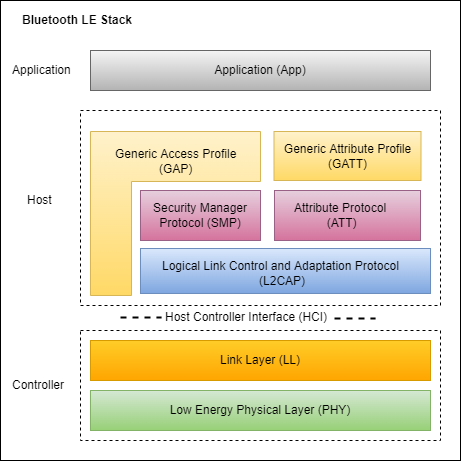

The L2CAP layer in Bluetooth LE corresponds to the higher sub-layer i.e. Logical Link Control (LLC) of the Data Link Layer in the OSI reference model. The L2CAP is above the PHY and Link Layer of Bluetooth LE. The Bluetooth LE specification optimized and simplified the L2CAP when compared to classic Bluetooth.

**L2CAP** in Bluetooth LE is responsible for: 

- Logical connection establishment

- Protocol multiplexing

- Segmentation and reassembly

- Flow control per 'dynamic' L2CAP channel.

The L2CAP layer adds an L2CAP basic header to the higher-layer payload and passes the Protocol Data Unit (PDU) to the Link Layer below it.

                                                              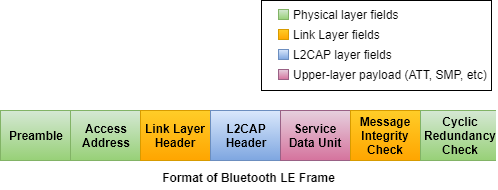         

## L2CAP Frames

L2CAP Frames consist of two sub-categories: **Data frames** and **Signaling frames**. There are different types of frames within these two categories of frames. The *Data frames* are again sub-categorized into *B-frame* (Basic information frame) and *LE-frame* (Low Energy information frame). Each frame type has its own format.

A **channel identifier (CID)** is the local name representing a logical channel endpoint on the device. For the protocols, such as the ATT and SMP, these channels are *fixed* by the Bluetooth Special Interest Group (SIG). For application specific profiles, such as Internet Protocol Support Profile (IPSP) and Object Transfer Profile (OTP), these channels are *dynamically* allocated.

**Signaling frames** are used with a fixed logical channel called signaling channel (**'0005'**) and used for logical connection establishment between peer devices using the LE credit based flow control mechanism. These signaling frames are also used for updating the connection parameters (Peripheral latency, Connection timeout, Minimum connection interval and Maximum connection interval) when connection parameters request procedure is not supported in the Link Layer.

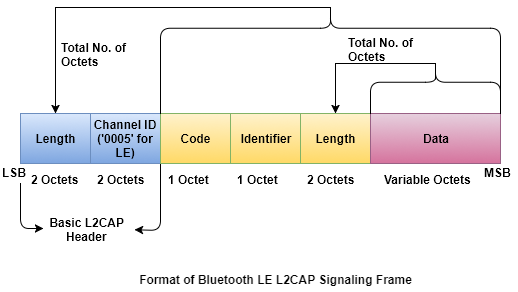

**Data frames (B-frames and LE-frames)** carry the upper-layer payload as 'Information Payload' in its frame format. *B-Frames* are used to carry fixed channels (ATT and SMP with fixed logical channels **'0004'** and **'0006'** respectively) payload. *LE-frames* are used to carry payload through dynamically created logical channels for application specific profiles, such as IPSP and OTP.

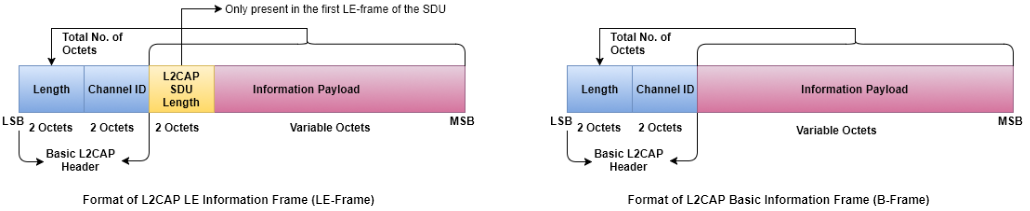

This example illustrates generation and decoding of the following frames. For a list of other signaling frames supported, see the `CommandType` property of [bleL2CAPFrameConfig](docid:bluetooth_ref#obj_bleL2CAPFrameConfig) object.

*1. Flow control credit:* This signaling frame is sent to create and configure an L2CAP logical channel between two devices.

*2. B-frames over fixed channels (ATT, SMP, etc.):* This frame is used for carrying fixed channels payload in basic L2CAP mode.

*3. LE-frames over dynamic channels (profiles like IPSP, OTP, etc.):* This frame is used for carrying dynamic channels payload in LE credit based flow control mode.

## L2CAP Frames Generation

You can use the [bleL2CAPFrame](docid:bluetooth_ref#fcn_bleL2CAPFrame) function to generate an L2CAP frame. This function accepts a configuration object [bleL2CAPFrameConfig](docid:bluetooth_ref#obj_bleL2CAPFrameConfig). This object configures the fields required for generating an L2CAP frame.

**Signaling frame generation**

To generate a signaling frame, create a [bleL2CAPFrameConfig](docid:bluetooth_ref#obj_bleL2CAPFrameConfig) object with `ChannelIdentifier` set to `'0005'`.

cfgL2CAP = bleL2CAPFrameConfig('ChannelIdentifier', '0005');

Configure the fields:

% Command type
cfgL2CAP.CommandType = 'Flow control credit';

% Source channel identifier
cfgL2CAP.SourceChannelIdentifier = '0041';

% LE credits
cfgL2CAP.Credits = 25

cfgL2CAP =   bleL2CAPFrameConfig with properties:

          ChannelIdentifier: '0005'
                CommandType: 'Flow control credit'
           SignalIdentifier: '01'
    SourceChannelIdentifier: '0041'
                    Credits: 25


Generate a 'Flow control credit' command.

sigFrame = bleL2CAPFrame(cfgL2CAP);

**B-frame generation**

To generate a B-frame (carrying ATT PDU), create a [bleL2CAPFrameConfig](docid:bluetooth_ref#obj_bleL2CAPFrameConfig) object with `ChannelIdentifier` set to `'0004'` (ATT channel ID).

cfgL2CAP = bleL2CAPFrameConfig('ChannelIdentifier', '0004')

cfgL2CAP =   bleL2CAPFrameConfig with properties:

    ChannelIdentifier: '0004'


A B-frame is used to transmit payload from the ATT upper-layer. A 5-byte ATT PDU is used as payload in this example.

payload = ['04';'01';'00';'FF';'FF'];

Generate an L2CAP B-frame using the payload and configuration.

bFrame = bleL2CAPFrame(cfgL2CAP, payload);

**LE-frame generation**

To generate an LE-frame, create a [bleL2CAPFrameConfig](docid:bluetooth_ref#obj_bleL2CAPFrameConfig) object with `ChannelIdentifier` set to `'0035'`.

cfgL2CAP = bleL2CAPFrameConfig('ChannelIdentifier', '0035')

cfgL2CAP =   bleL2CAPFrameConfig with properties:

    ChannelIdentifier: '0035'


An LE-frame is used to transmit the payload of dynamic channels. A 2-byte payload is used in this example.

payload = ['01';'02'];

Generate an L2CAP LE-frame using the payload and configuration.

leFrame = bleL2CAPFrame(cfgL2CAP, payload);

## Decoding L2CAP Frames

You can use the [bleL2CAPFrameDecode](docid:bluetooth_ref#fcn_bleL2CAPFrameDecode) function to decode an L2CAP frame. This function outputs the following information:

- `status`: An enumeration of type `blePacketDecodeStatus`, which indicates whether or not the L2CAP decoding was successful.

- `cfgL2CAP`: An L2CAP frame configuration object of type [bleL2CAPFrameConfig](docid:bluetooth_ref#obj_bleL2CAPFrameConfig), which contains the decoded L2CAP properties.

This function accepts a Bluetooth LE L2CAP frame as the input.

**Decoding Signaling frame**

[sigFrameDecodeStatus, cfgL2CAP] = bleL2CAPFrameDecode(sigFrame);

Observe the outputs

% Decoding is successful
if strcmp(sigFrameDecodeStatus, 'Success')
    fprintf('L2CAP decoding status is: %s\n\n', sigFrameDecodeStatus);
    fprintf('Received L2CAP signaling frame configuration is:\n');
    cfgL2CAP
% Decoding failed
else
    fprintf('L2CAP decoding status is: %s\n', sigFrameDecodeStatus);
end

L2CAP decoding status is: Success



Received L2CAP signaling frame configuration is:


cfgL2CAP =   bleL2CAPFrameConfig with properties:

          ChannelIdentifier: '0005'
                CommandType: 'Flow control credit'
           SignalIdentifier: '01'
    SourceChannelIdentifier: '0041'
                    Credits: 25


**Decoding B-frame**

[bFrameDecodeStatus, cfgL2CAP, payload] = bleL2CAPFrameDecode(bFrame);

Observe the outputs

% Decoding is successful
if strcmp(bFrameDecodeStatus, 'Success')
    fprintf('L2CAP decoding status is: %s\n\n', bFrameDecodeStatus);
    fprintf('Received L2CAP B-frame configuration is:\n');
    cfgL2CAP
    fprintf('Payload carried by L2CAP B-frame is:\n');
    payload
% Decoding failed
else
    fprintf('L2CAP decoding status is: %s\n', bFrameDecodeStatus);
end

L2CAP decoding status is: Success



Received L2CAP B-frame configuration is:


cfgL2CAP =   bleL2CAPFrameConfig with properties:

    ChannelIdentifier: '0004'


Payload carried by L2CAP B-frame is:


payload = 5×2 char array
    '04'
    '01'
    '00'
    'FF'
    'FF'


**Decoding LE-frame**

[leFrameDecodeStatus, cfgL2CAP, payload] = bleL2CAPFrameDecode(leFrame);

Observe the outputs

% Decoding is successful
if strcmp(leFrameDecodeStatus, 'Success')
    fprintf('L2CAP decoding status is: %s\n\n', leFrameDecodeStatus);
    fprintf('Received L2CAP LE-frame configuration is:\n');
    cfgL2CAP
    fprintf('Payload carried by L2CAP LE-frame is:\n');
    payload
% Decoding failed
else
    fprintf('L2CAP decoding status is: %s\n', leFrameDecodeStatus);
end

L2CAP decoding status is: Success



Received L2CAP LE-frame configuration is:


cfgL2CAP =   bleL2CAPFrameConfig with properties:

    ChannelIdentifier: '0035'


Payload carried by L2CAP LE-frame is:


payload = 2×2 char array
    '01'
    '02'


## Exporting to a PCAP File

This example uses [blePCAPWriter](docid:bluetooth_ref#mw_28e190f2-8546-4ccd-b1d9-a84bb841307a) object to export the generated PDUs to a file with .pcap extension or .pcapng extension. To analyze and visualize this file, use a third part packet analyzer such as Wireshark [ 3 ].

The PCAP format expects L2CAP frame to be enclosed within Link Layer packet and also expects the generated packet to be prepended with the access address. The following commands generate a PCAP file for the L2CAP frames generated in this example.

% Create a cell array of L2CAP frames
l2capFrames = {sigFrame, bFrame, leFrame};
llPackets = cell(1, numel(l2capFrames));
for i = 1:numel(llPackets)
    % Add Link Layer header to the generated L2CAP frame
    cfgLLData = bleLLDataChannelPDUConfig('LLID', 'Data (start fragment/complete)');
    llDataPDU = bleLLDataChannelPDU(cfgLLData, l2capFrames{i});
    % Prepend access address. A 4-byte access address is used in this example
    llPackets{i} = [int2bit(hex2dec('01234567'), 32, false); llDataPDU];
end

**Export to a PCAP file**

Create an object of type [blePCAPWriter](docid:bluetooth_ref#mw_28e190f2-8546-4ccd-b1d9-a84bb841307a) and specify the packet capture file name.

% Create the Bluetooth LE PCAP Writer file object
pcapObj = blePCAPWriter("FileName", "bluetoothLEL2CAPFrames4");

Error using pcapWriter
File with the name bluetoothLEL2CAPFrames4 already exists. Use a different file name.

Error in blePCAPWriter (line 373)
                obj.PCAPPacketWriter = pcapWriter('FileName', pcapFileName,...

Use the [write](docid:bluetooth_ref#mw_28e190f2-8546-4ccd-b1d9-a84bb841307a) function to write all the Bluetooth LE LL PDUs to a PCAP file. The constant `timestamp` specifies the capture time of a PDU. In this example, the capture time is same for all the PDUs.

timestamp = 124800; % timestamp (in microseconds)
 
% Write all the LL PDUs to the PCAP file
for idx = 1:numel(llPackets)
    write(pcapObj, llPackets{idx}, timestamp, "PacketFormat", "bits");
end
 
% Clear the object
clear pcapObj;

## Visualization of the Generated L2CAP Frames

You can open the PCAP file containing the generated L2CAP frames in a packet analyzer. The L2CAP frames decoded by the packet analyzer match the standard compliant L2CAP frames generated by Bluetooth® Toolbox. The captured analysis of the L2CAP frames is shown below.

- **Signaling frame (flow control credit)**

          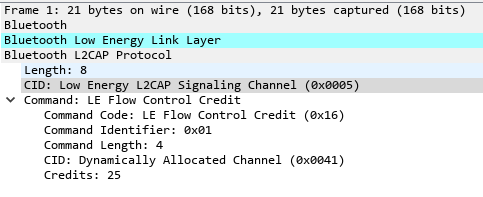

- **B-frame (carrying ATT PDU)**

          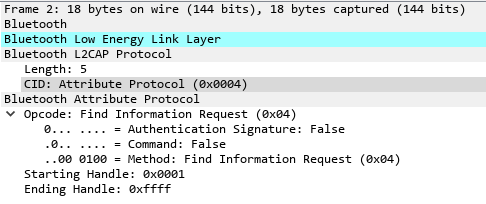

- **LE-frame (carrying dynamic channel payload)**

          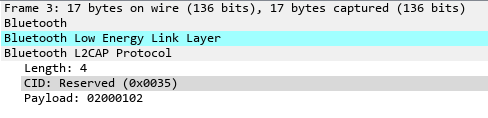

## Conclusion

This example demonstrated generation and decoding of L2CAP frames specified in the Bluetooth [ 2 ] standard. You can use a packet analyzer to view the generated L2CAP frames.

## Selected Bibliography

- Bluetooth Technology Website. “Bluetooth Technology Website | The Official Website of Bluetooth Technology.” Accessed November 25, 2021. [https://www.bluetooth.com](https://www.bluetooth.com).

- Bluetooth Special Interest Group (SIG). "Bluetooth Core Specification." Version 5.3. [https://www.bluetooth.com/.](https://www.bluetooth.com)

- "Development/LibpcapFileFormat - The Wireshark Wiki." [https://wiki.wireshark.org/Development/LibpcapFileFormat.](https://wiki.wireshark.org/Development/LibpcapFileFormat)

- Group, The Tcpdump. "Tcpdump/Libpcap Public Repository." [https://www.tcpdump.org](https://www.tcpdump.org).

*Copyright 2018-2021 The MathWorks, Inc.*